AUTOR: Jean Sebastian Posada Neira

##                               **  PRACTICA II DSP**

El trabajo consiste en construir un programa de computador que tome una señal de voz y clasifique, para  cada instante de tiempo, si la señal corresponde a silencios, sonidos no-vocalizados o sonidos vocalizados.  El programa se debe verificar tanto con la señal vozfemenina.wav como con otra señal de voz grabada por  usted mismo, que sea apropiada para verificar el programa propuesto. Aunque la obtención de las señales  de energía y tasa de cruces por cero en tiempo corto ya está especificada, las técnicas de procesamiento  pueden incluir desde simples ciclos de histéresis sobre niveles de comparación juiciosamente  determinados hasta técnicas de machine learning (lógica difusa, redes neuronales, etc.) con procesos  apropiados de entrenamiento. 

 PRIMER AUDIO: vozfemenina.wav 

[x, fs] = audioread('vozfemenina.wav');
x = x(:,1);
x = x / max(abs(x));% Si el audio es estéreo, toma solo un canal (mono) se convierte la señal a mono para simplificar el procesamiento, ya que el análisis en tiempo corto se realiza sobre una única dimensión.

t = (0:length(x)-1)/fs;% Crea el vector de tiempo en segundos

frame_length = round(0.03 * fs);%Longitud de ventana originalmente se establecio como (30ms).
frame_shift  = round(0.015 * fs);% Desplazamiento entre ventanas (15 ms → 50% overlap) osea cada ventana comparte la mitad de sus muestras con la anterior.

num_frames = floor((length(x) - frame_length)/frame_shift) + 1;% Número total de ventanas

energy = zeros(num_frames,1);
zcr    = zeros(num_frames,1);
% Inicializa vectores de energía y tasa de cruces por cero (ZCR)
for i = 1:num_frames
    idx = (i-1)*frame_shift + (1:frame_length); % Índices de la ventana actual
    frame = x(idx);% Extrae el segmento de señal
    
    energy(i) = sum(frame.^2); % Calcula la energía en tiempo corto
    zcr(i) = sum(abs(diff(sign(frame)))) / (2*frame_length);% Calcula la tasa de cruces por cero
end

energy = energy / max(energy);% Normaliza la energía
zcr = zcr / max(zcr);% Normaliza la ZCR

% Umbrales
th_energy_silence = 0.02;% Umbral para detectar silencio
th_energy_voiced  = 0.4 * mean(energy);% Umbral para detectar voz (adaptativo, osea que se ajusta dependiendo de la señal por lo que puede funcionar con varias grabaciones)
th_zcr = 0.8 * mean(zcr);% Umbral para distinguir ruido/voz

levels = zeros(num_frames,1);% Vector de clasificación (0, 2.5, 5) para que parezca señal digital como se hara mas adelante.

for i = 1:num_frames
    if energy(i) < th_energy_silence
        levels(i) = 0;% Silencio
    elseif energy(i) > th_energy_voiced && zcr(i) < th_zcr
        levels(i) = 2.5;% Vocalizado
    else
        levels(i) = 5;% No vocalizado
    end
end

% Guardamos resultados de la voz femenina en 1
res1.silencio = sum(levels == 0)/num_frames * 100;
res1.vocalizado = sum(levels == 2.5)/num_frames * 100;
res1.no_vocalizado = sum(levels == 5)/num_frames * 100;

res1.energy_mean = mean(energy);
res1.zcr_mean = mean(zcr);

 SEGUNDO AUDIO: AudioSebastian.wav (repetimos el proceso)

[x, fs] = audioread('AudioSebastian.wav');
x = x(:,1);
x = x / max(abs(x));

t = (0:length(x)-1)/fs;

frame_length = round(0.03 * fs);
frame_shift  = round(0.015 * fs);

num_frames = floor((length(x) - frame_length)/frame_shift) + 1;

energy = zeros(num_frames,1);
zcr    = zeros(num_frames,1);

for i = 1:num_frames
    idx = (i-1)*frame_shift + (1:frame_length);
    frame = x(idx);
    
    energy(i) = sum(frame.^2);
    zcr(i) = sum(abs(diff(sign(frame)))) / (2*frame_length);
end

energy = energy / max(energy);
zcr = zcr / max(zcr);

% Mismos umbrales
th_energy_silence = 0.02;
th_energy_voiced  = 0.4 * mean(energy);
th_zcr = 0.8 * mean(zcr);

levels = zeros(num_frames,1);

for i = 1:num_frames
    if energy(i) < th_energy_silence
        levels(i) = 0;
    elseif energy(i) > th_energy_voiced && zcr(i) < th_zcr
        levels(i) = 2.5;
    else
        levels(i) = 5;
    end
end

% Guardar resultados 2
res2.silencio = sum(levels == 0)/num_frames * 100;
res2.vocalizado = sum(levels == 2.5)/num_frames * 100;
res2.no_vocalizado = sum(levels == 5)/num_frames * 100;

res2.energy_mean = mean(energy);
res2.zcr_mean = mean(zcr);

COMPARACIÓN 

tabla = table( ...
    [res1.silencio; res2.silencio], ...
    [res1.vocalizado; res2.vocalizado], ...
    [res1.no_vocalizado; res2.no_vocalizado], ...
    [res1.energy_mean; res2.energy_mean], ...
    [res1.zcr_mean; res2.zcr_mean], ...
    'VariableNames', {'Silencio_%','Vocalizado_%','NoVocalizado_%','Energia','ZCR'}, ...
    'RowNames', {'VozFemenina','AudioSebastian'} ...
);

disp(tabla)

 Gráfica de clasificación

VOZ FEMENINA 

[x1, fs1] = audioread('vozfemenina.wav');
x1 = x1(:,1);
x1 = x1 / max(abs(x1));

t1 = (0:length(x1)-1)/fs1;

frame_length = round(0.03 * fs1);
frame_shift  = round(0.015 * fs1);

num_frames = floor((length(x1) - frame_length)/frame_shift) + 1;

energy = zeros(num_frames,1);
zcr    = zeros(num_frames,1);

for i = 1:num_frames
    idx = (i-1)*frame_shift + (1:frame_length);
    frame = x1(idx);
    
    energy(i) = sum(frame.^2);
    zcr(i) = sum(abs(diff(sign(frame)))) / (2*frame_length);
end

energy = energy / max(energy);
zcr = zcr / max(zcr);

th_energy_silence = 0.02;
th_energy_voiced  = 0.4 * mean(energy);
th_zcr = 0.8 * mean(zcr);

levels1 = zeros(num_frames,1);% Vector donde se guardará la clasificación

for i = 1:num_frames
    if energy(i) < th_energy_silence
        levels1(i) = 0;
    elseif energy(i) > th_energy_voiced && zcr(i) < th_zcr
        levels1(i) = 2.5;
    else
        levels1(i) = 5;
    end
end

t_frames1 = ((0:num_frames-1)*frame_shift + frame_length/2)/fs1;% Genera el tiempo asociado a cada ventana (centro de la ventana)

levels_plot1 = interp1(t_frames1, levels1, t1, 'nearest', 'extrap');% Interpola la clasificación para ajustarla al tamaño de la señal original
% 'nearest' mantiene valores discretos (tipo digital)

% ----------- MI VOZ -----------%repetimos el proceso-------
[x2, fs2] = audioread('AudioSebastian.wav');
x2 = x2(:,1);
x2 = x2 / max(abs(x2));

t2 = (0:length(x2)-1)/fs2;

frame_length = round(0.03 * fs2);
frame_shift  = round(0.015 * fs2);

num_frames = floor((length(x2) - frame_length)/frame_shift) + 1;

energy = zeros(num_frames,1);
zcr    = zeros(num_frames,1);

for i = 1:num_frames
    idx = (i-1)*frame_shift + (1:frame_length);
    frame = x2(idx);
    
    energy(i) = sum(frame.^2);
    zcr(i) = sum(abs(diff(sign(frame)))) / (2*frame_length);
end

energy = energy / max(energy);
zcr = zcr / max(zcr);

th_energy_silence = 0.02;
th_energy_voiced  = 0.4 * mean(energy);
th_zcr = 0.8 * mean(zcr);

levels2 = zeros(num_frames,1);

for i = 1:num_frames
    if energy(i) < th_energy_silence
        levels2(i) = 0;
    elseif energy(i) > th_energy_voiced && zcr(i) < th_zcr
        levels2(i) = 2.5;
    else
        levels2(i) = 5;
    end
end

t_frames2 = ((0:num_frames-1)*frame_shift + frame_length/2)/fs2;
levels_plot2 = interp1(t_frames2, levels2, t2, 'nearest', 'extrap');

GRÁFICAS

figure;

subplot(2,1,1)
stairs(t1, levels_plot1, 'LineWidth', 1.5)
title('Clasificación - Voz femenina')
ylim([-0.5 5.5])
yticks([0 2.5 5])
yticklabels({'Silencio','Vocalizado','No vocalizado'})
grid on

subplot(2,1,2)
stairs(t2, levels_plot2,'r', 'LineWidth', 1.5)
title('Clasificación - AudioSebastian')
ylim([-0.5 5.5])
yticks([0 2.5 5])
yticklabels({'Silencio','Vocalizado','No vocalizado'})
grid on

FIGURA 2 Solo señales (ambos audios) 

figure(2);

% ----------- VOZ FEMENINA -----------
subplot(2,1,1)
plot(t1, x1, 'b', 'LineWidth', 1.2)

title('Voz femenina')
xlabel('Tiempo (s)')
ylabel('Amplitud')
grid on

% ----------- MI VOZ -----------
subplot(2,1,2)
plot(t2, x2, 'r', 'LineWidth', 1.2)

title('Mi voz')
xlabel('Tiempo (s)')
ylabel('Amplitud')
grid on

%%===========Solo si lo desea puede reproducir ambos audios======
%============Voz femenina=====================================
%sound(x1,fs1)
%============Mi audio=====================================
%sound(x2,fs2)


RESULTADOS

Grafica de clasificacion

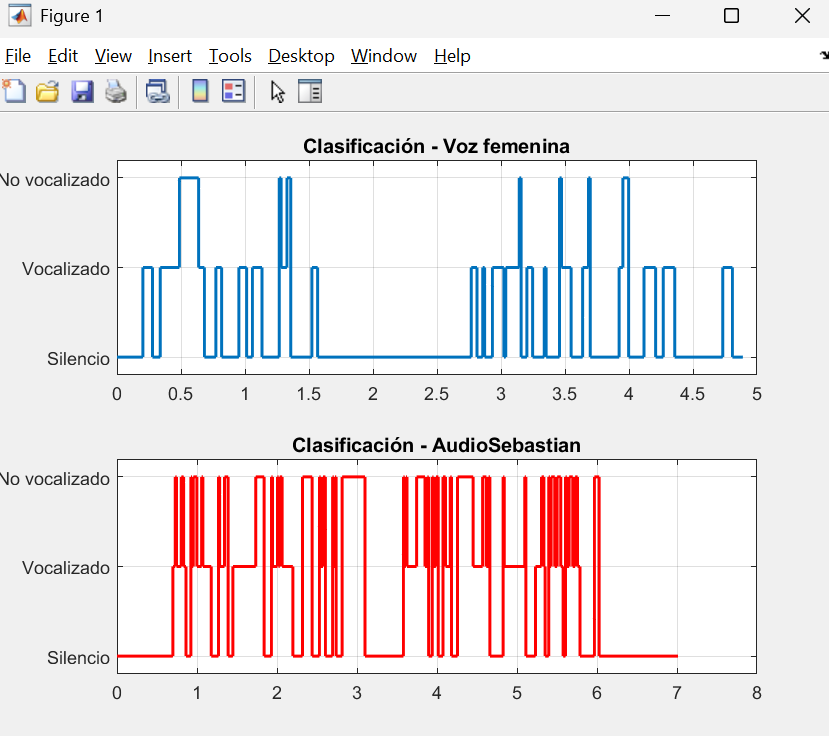

%Graficas señales

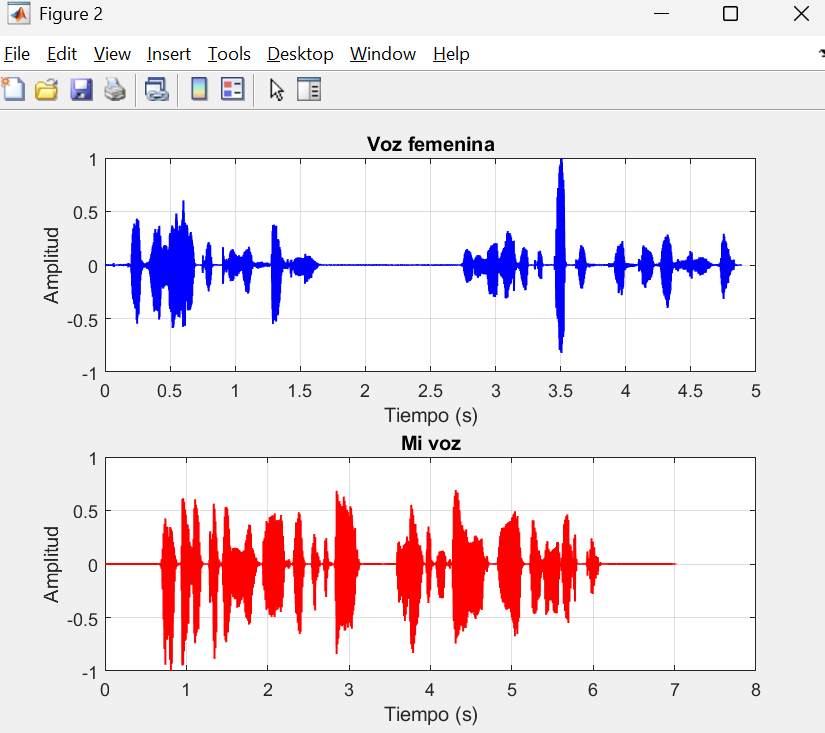

## Conclusiones

En este trabajo se desarrolló un sistema de clasificación de señales de voz basado en el análisis en tiempo corto, utilizando como características principales la energía y la tasa de cruces por cero (ZCR). Este enfoque permitió segmentar la señal en intervalos donde se asume un comportamiento casi estacionario, lo cual es fundamental para el procesamiento de señales de voz.

Durante el desarrollo se tomaron diversas decisiones de ingeniería, como la selección de ventanas de 30 ms con un solapamiento del 50%, buscando un equilibrio entre resolución temporal y estabilidad en las características extraídas. Asimismo, se implementaron criterios de clasificación basados en umbrales, incluyendo un enfoque adaptativo para la energía y la ZCR, lo que permitió mejorar la robustez del algoritmo frente a variaciones en la intensidad y características de las señales analizadas.

Los resultados obtenidos evidencian que el método es efectivo para distinguir entre segmentos de silencio, sonidos vocalizados y no vocalizados, especialmente cuando se comparan diferentes tipos de voz, como voz femenina y masculina. Sin embargo, también se identifican limitaciones inherentes al modelo, ya que la simplificación de la señal mediante características como la energía y la ZCR no captura completamente la complejidad del aparato fonador humano. En particular, existen ambigüedades en la clasificación durante transiciones suaves entre sonidos o en presencia de ruido.

Esto pone de manifiesto la distancia entre el modelo matemático empleado y la realidad física de la producción de voz, donde intervienen múltiples factores no considerados en el análisis, como la articulación, la entonación y la variabilidad entre hablantes. A pesar de estas limitaciones, el sistema desarrollado representa una solución eficiente y computacionalmente sencilla, adecuada como aproximación inicial al problema de segmentación de voz.

Finalmente, este trabajo demuestra la importancia de comprender tanto las capacidades como las limitaciones de los modelos utilizados en procesamiento digital de señales, así como la necesidad de tomar decisiones de ingeniería fundamentadas para lograr soluciones prácticas y funcionales.

En caso de querer tener el archivo .m  original y el AudioSebastian.wav ingresar a la siguiente carpeta en  [OneDrive](https://udistritaleduco-my.sharepoint.com/:f:/g/personal/jsposadan_udistrital_edu_co/IgAkDD_w08EGS6GZEVNOv48HAZ_33zkRY7pxIpchvQFIkjY?e=91uM8X)